% 1. 노이즈가 섞인 정현파가 나오도록 reference signal 만들기

clear all; clc;

fs=1000; % sampling freq [HZ]
Tmax=5; % signal length [sec]
t=[0:1/fs:Tmax-1/fs]; % signal sample idx [sample(fs=1000)]
f=5; % signal freq [HZ]

x=sin(2*pi*f.*t)+0.50*randn(1,length(t)); % random noise

## plotting x & d signal (figure 1)

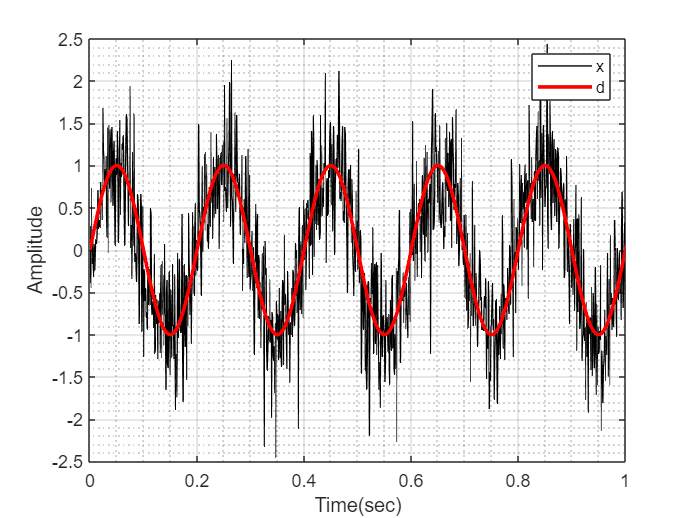

%2. Reference signal과 desired signal(sin함수)함께 그래프로 출력해보기

figure(1); clf;
hold on;

d=sin(2*pi*f.*t); % desired signal d
plot(t,x,'k','LineWidth',0.75)
plot(t,d,'r','Linewidth',2)
grid on; grid minor; box on;
%xlim([0 0.2])
xlim([0 1])
%xlim([-1 6])
ylim([-2.5 2.5])
xlabel('Time(sec)')
ylabel('Amplitude')
legend('x','d')

## Design Wiener Filter

% 3. Wiener filter 값을 도출

filter_length=100; % Wiener filter length [sample]
N=numel(d); % d signal length

r=xcorr(x); % auto-correlation of x

for i=1:1:filter_length
    rxx(i)=r(N+i-1);
end

Rxx=toeplitz(rxx); % toeplitz matrix with rxx

p=xcorr(d,x); % cross-correlation of x & d

for i=1:1:filter_length
    pxd(i)=p(N+i-1);
end

w_filter=(inv(Rxx))*pxd'; % optimal filter


## plotting Wiener filter ( figure 2)

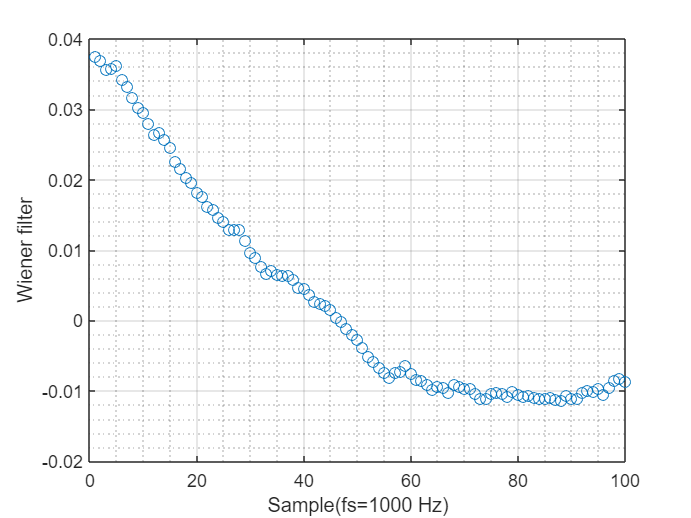

% 3. Wiener filter 그래프 출력


figure(2); clf;
plot(w_filter,'o')
grid on; grid minor; box on;
xlabel('Sample(fs=1000 Hz)'); ylabel('Wiener filter');

## Test Wiener filter

% 4. 노이즈 섞인 reference signal을 wiener filter를 통해 filtering하기
% 즉, y 구하기

y=filter(w_filter,1,x); % filters reference signal

## plotting Wiener filter output signal (figure 3)

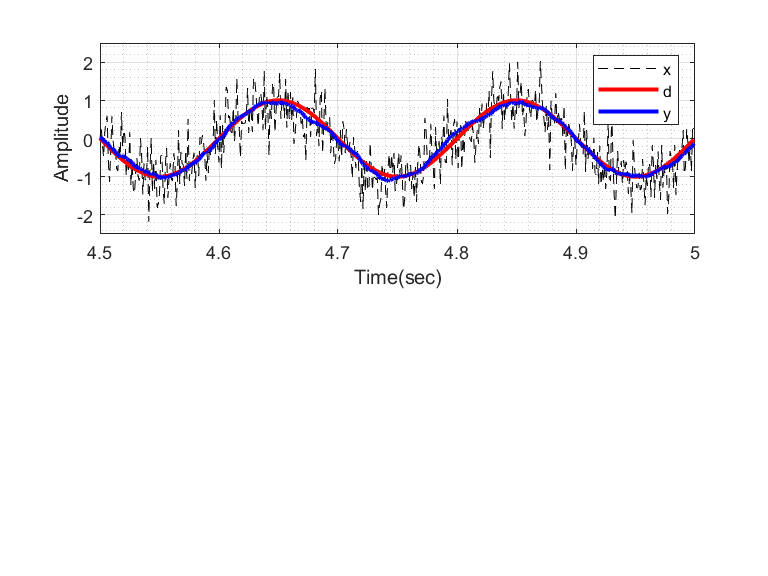

% 4. Filtering된 reference signal를 출력하기
% filtering된 reference signal = y

figure(3);  subplot(2,1,1); hold on;
plot(t,x,'k--')
plot(t,d,'r','LineWidth',2)
plot(t,y,'b','LineWidth',2)
grid on; grid minor; box on;
xlim([4.5 5]); ylim([-2.5 2.5])
xlabel('Time(sec)'); ylabel('Amplitude')
legend('x','d','y')

## error signal (figure 4)

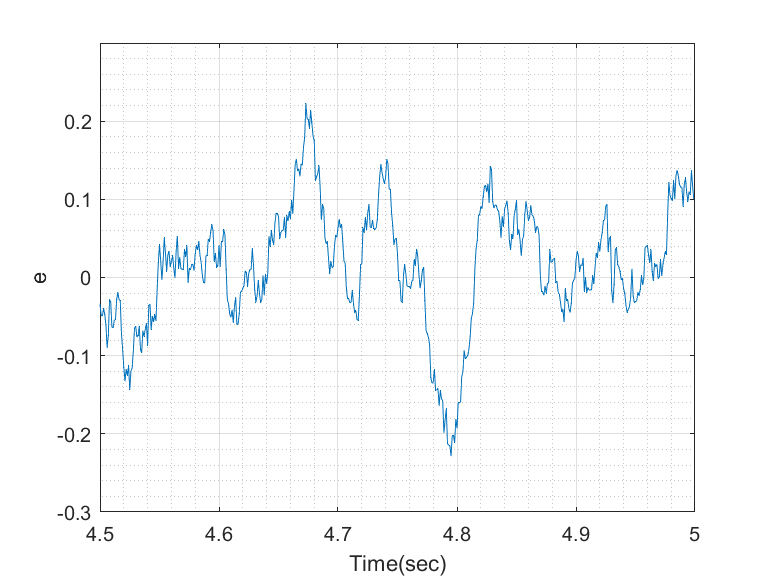

%5. Filtering된 reference signal의 error signal 구해서 그래프로 나타내기

figure(4);
e=d-y; % error signal
plot(t,e)
grid on; grid minor; box on;
xlim([4.5 5]); ylim([-0.3 0.3])
xlabel('Time(sec)'); ylabel('e')

MSE=mean(e.^2) % mse of error signal

MSE = 0.0076

## Winer filter length vs MSE ( figure 5)

% 6. Wiener filter 개수에 대한 Cost Function 그래프, 공학적 의미

clear all; clc;

  % 똑같이 noise 있는 reference signal 생성
fs=1000; % sampling freq [HZ]
Tmax=5; % signal length [sec]
t=[0:1/fs:Tmax-1/fs]; % signal sample idx [sample(fs=1000)]
f=5; % signal freq [HZ]
x=sin(2*pi*f.*t)+0.50*randn(1,length(t)); % random noise
d=sin(2*pi*f.*t); % desired signal d

filter_L=1:10:500

filter_L =      1    11    21    31    41    51    61    71    81    91   101   111   121   131   141   151   161   171   181   191   201   211   221   231   241   251   261   271   281   291   301   311   321   331   341   351   361   371   381   391   401   411   421   431   441   451   461   471   481   491


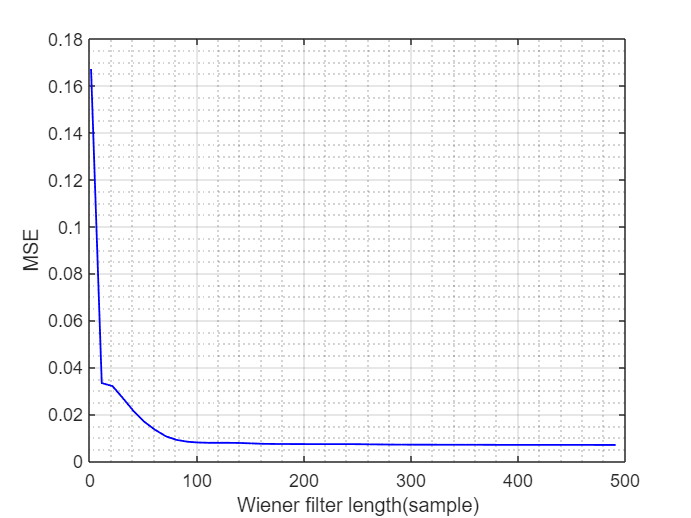

MSE=[];
N=numel(d);
r=xcorr(x);
p=xcorr(d,x);
for LL = filter_L
    filter_length=LL;
    for i=1:1:filter_length
        rxx(i)=r(N+i-1);
    end
    Rxx=toeplitz(rxx);
    for i=1:1:filter_length
        pxd(i)=p(N+i-1);
    end
    w_filter=(inv(Rxx))*pxd';
    y=filter(w_filter,1,x);
    e=d-y;
    MSE=[MSE mean(e.^2)];
end

figure(4); clf;
plot(filter_L,MSE,'b','LineWidth',1)
grid on; grid minor; box on;
xlabel('Wiener filter length(sample)'); ylabel('MSE');